# Exercice 1 

### Application Numérique

P = [0.7 0.1 0.2];
%Faire varier N pour se rapprocher de la solution
N = 100000;
%On remplace les valeurs entre 1 et 3 par les valeurs de Taille
Taille = [64 128 512];
%Compteurs pour le nombre de paquets de chaque taille
n1 = 0; n2 = 0; n3 = 0;

for i=1:N
    X = Loi_emp(P);
    if Taille(X) == 64
        n1 = n1+1;
    elseif Taille(X) == 128
        n2 = n2+1;
    else
        n3 = n3+1;
    end
end
Distribution_simulee = [n1/N n2/N n3/N]

Distribution_simulee =     0.6968    0.1011    0.2021


# Exercice 2

### Application Numérique

#### Question b

lambda = 20;
N = 100000;
X = [];
for i=1:N
    X(i) = loi_expo(lambda);
end
Moyenne = mean(X) %moyenne théorique 1/lambda

Moyenne = 0.0500

Variance = var(X) %Variance théorique 1/lambda²

Variance = 0.0025


%Intervalle de confiance
IC95 = [Moyenne-1.98*sqrt(Variance)/sqrt(N), Moyenne+1.98*sqrt(Variance)/sqrt(N)]

IC95 =     0.0497    0.0503


#### Question c

%Temps moyen 15s donc lambda = 1/15
lambda = 1/15;
N = 100000;
%Compteur
n = 0;
X = [];
for i=1:N
    X = loi_expo(lambda);
    if X <= 10
        n = n+1;
    end
end
Proba = n/N

Proba = 0.4868

### Question 2

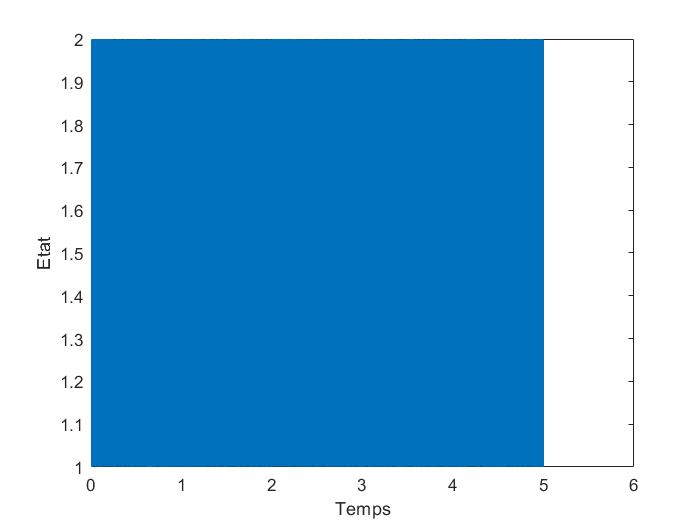

P0 = [1 0]; %état initial, on est à l'état 0
lambda = 1000; %Requêtes/secondes
mu = 2000; %Requêtes/secondes
M = [-lambda, lambda; mu , -mu];
T = 5;
[X, t] = CMTC(M, P0, T);


%Calcul du taux d'occupation
Temps = 0;
for i=1:length(X)
    if X(i) == 2
        Temps = Temps + t(i) - t(i-1);
    end
end

Taux_occupation = Temps/t(i) %valeur théorique = 1/3

Taux_occupation = 0.3340

# Exercice 1

### Question a : Fonction de distribution empirique

function [X] = Loi_emp(P)
F=[]; %Initialisation
F(1)=P(1); 
n=length(P);
for i=2:n
   F(i)=F(i-1)+P(i);
end

%u est une variable uniformément distribué entre 0 et 1
u=rand; %u ~ U(0,1)

Ind=find(F>u);
X = Ind(1);
end


# Exercice 2

### Question a : Fonction de distribution exponentielle

function X = loi_expo(lambda)
    u=rand;
    X=-log(u)/lambda;
end

### Question 2 : Chaine de Markov à Temps Continu (CMTC)

function [X t] = CMTC(M, P0, T)
% P0 = distribution empirique pour l'état initial
% M = Matrice de taux de transition
% T = Durée d'observation

n = length(P0); %Nbr des états possibles
Q = M;
for i=1:n
    Q(i, :) = -M(i,:)/M(i, i);
    Q(i,i)=0;
end

X(1) = Loi_emp(P0); % Etat initial
t(1) = loi_expo(-M(X(1), X(1))); % Temps de séjour pour l'état initial

i = 1;
while(t(i) < T)
    X(i+1) = Loi_emp(Q(X(i),:)); % Génération de l'état suivant
    temp = loi_expo(-M(X(i+1), X(i+1)));
    t(i+1) = t(i) + temp;
    i = i+1;
end

stairs(t,X); xlabel('Temps'); ylabel('Etat');

end